# Q1


$$f\left(x\right)=\left\lbrace \begin{array}{cc}
x & 0\le x<3\\
x^2  & 3\le x<5
\end{array}\right.$$


f = @(x) x.*(0 <= x & x < 3) + (x.^2).*(3 <= x & x < 5)

f = function_handle with value:
    @(x)x.*(0<=x&x<3)+(x.^2).*(3<=x&x<5)


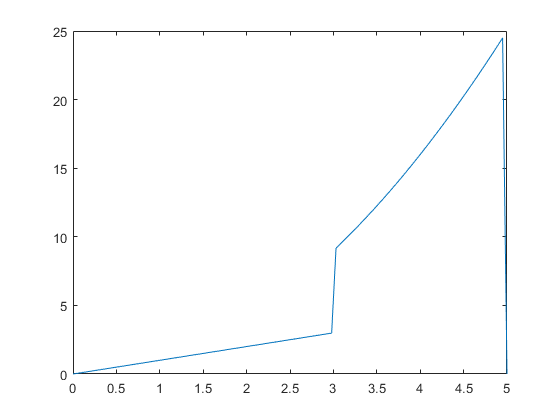

x = linspace(0, 5, 100);
y = f(x);
plot(x, y)

Plot the function in the interval [0, 15]

ncycle = (15-0)/(5-0)

ncycle = 3

y

y =          0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


ry = repmat(y, 1, 3)

ry =          0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


rx = linspace(0, 15, length(ry))

rx =          0    0.0502    0.1003    0.1505    0.2007    0.2508    0.3010    0.3512    0.4013    0.4515    0.5017    0.5518    0.6020    0.6522    0.7023    0.7525    0.8027    0.8528    0.9030    0.9532    1.0033    1.0535    1.1037    1.1538    1.2040    1.2542    1.3043    1.3545    1.4047    1.4548    1.5050    1.5552    1.6054    1.6555    1.7057    1.7559    1.8060    1.8562    1.9064    1.9565    2.0067    2.0569    2.1070    2.1572    2.2074    2.2575    2.3077    2.3579    2.4080    2.4582


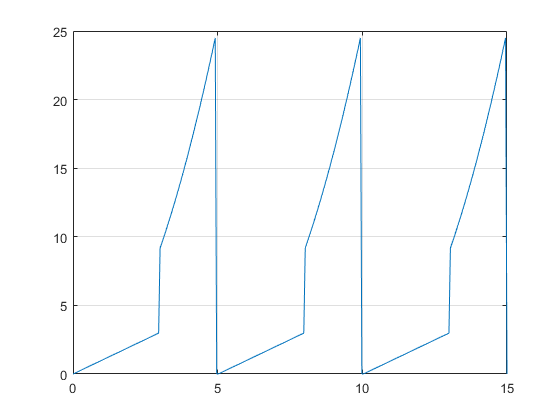

plot(rx, ry)
grid on

# Q2


$$f\left(x\right)=\left\lbrace \begin{array}{cc}
\frac{x^2 }{4} & 0\le x<4\\
4 & 4\le x<6\\
0 & 6\le x<8
\end{array}\right.$$
 
$$f\left(x+8\right)=f\left(x\right)$$


Period of the function = 8 = T

f = @(x) ((x.^2)/4).*(0<=x & x < 4) + 4.*(4<=x & x < 6) + 0.*(6 <= x & x < 8)

f = function_handle with value:
    @(x)((x.^2)/4).*(0<=x&x<4)+4.*(4<=x&x<6)+0.*(6<=x&x<8)


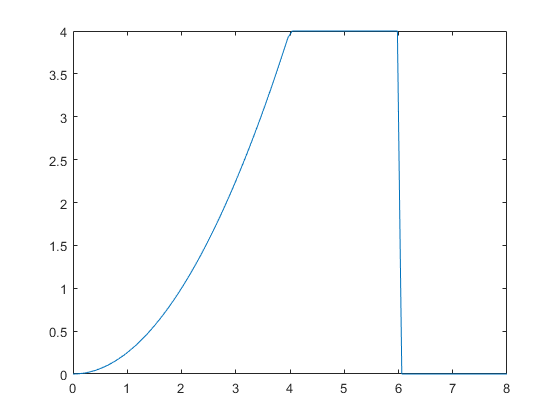

x = linspace(0, 8, 100); % since the function is periodic in interval 0 to 8, we insert 100 values into this interval
y = f(x); % evaluate the function in this interval

% sample plot in [0 8]
plot(x, y)

Now plot the function in the interval [-16 16]

ncycles = (16--16) / (8-0) = 4

ry = repmat(y, 1, 4);
rx = linspace(-16, 16, length(ry)) % linspace the new interval with the number of values inserted same as the length of ry

rx =   -16.0000  -15.9198  -15.8396  -15.7594  -15.6792  -15.5990  -15.5188  -15.4386  -15.3584  -15.2782  -15.1980  -15.1178  -15.0376  -14.9574  -14.8772  -14.7970  -14.7168  -14.6366  -14.5564  -14.4762  -14.3960  -14.3158  -14.2356  -14.1554  -14.0752  -13.9950  -13.9148  -13.8346  -13.7544  -13.6742  -13.5940  -13.5138  -13.4336  -13.3534  -13.2732  -13.1930  -13.1128  -13.0326  -12.9524  -12.8722  -12.7920  -12.7118  -12.6316  -12.5514  -12.4712  -12.3910  -12.3108  -12.2306  -12.1504  -12.0702


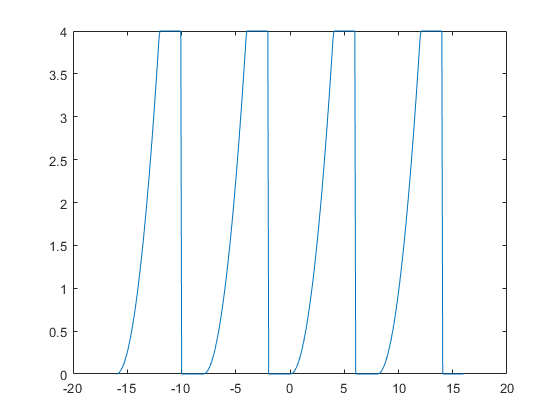

plot(rx, ry)